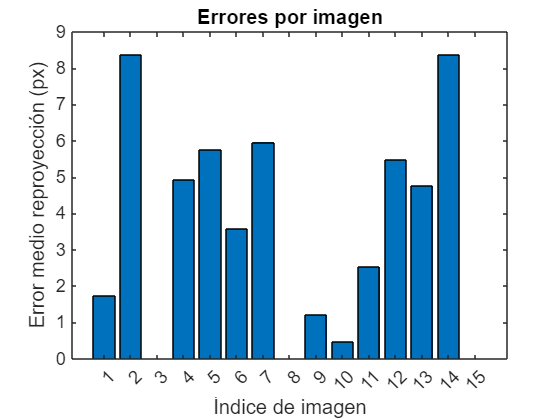

% Supongamos que ya tienes cameraParams_proyecto en workspace
% 1) Extraer el tamaño de imagen desde los parámetros Intrinsics
imageSize = cameraParams.Intrinsics.ImageSize;  
% Si por algún motivo no existiera esa propiedad, usa la primera foto:
%I = imread('fotos_cam\cal0.png');
%imageSize = [size(I,1), size(I,2)];

% Ahora sí recalibramos filtrando vistas con reproyección > 1 px
errors = cameraParams.ReprojectionErrors;  % [numCorners×2×numImages]
numImages = size(errors,3);
meanErr = zeros(numImages,1);
for i = 1:numImages
    perPoint = sqrt(sum(errors(:,:,i).^2,2));
    meanErr(i) = mean(perPoint);
end

% Visualizar para elegir umbral
figure; bar(meanErr);
xlabel('Índice de imagen'); ylabel('Error medio reproyección (px)');
title('Errores por imagen');


% Filtrar las buenas
threshold = 1;  % px
goodIdx = find(meanErr <= threshold);
fprintf('Usando %d de %d imágenes (umbral=%.1f px)\n', numel(goodIdx), numImages, threshold);

Usando 1 de 15 imágenes (umbral=1.0 px)



% Recalibrar con solo las buenas
% Supone que tienes imagePoints y worldPoints definidos en el mismo orden
%load('calibrationSession_proyecto.mat','imagePoints','worldPoints');  % ajusta a tu .mat
params_refined = estimateCameraParameters( ...
    imagePoints(:,:,goodIdx), worldPoints, ...
    'ImageSize', imageSize, ...
    'EstimateTangentialDistortion', true, ...
    'NumRadialDistortionCoefficients', 2);

Error using estimateCameraParameters>parseInputs (line 44)
The value of 'imagePoints' is invalid. Number of images containing the calibration pattern must be greater than or equal to 2.

Error in estimateCameraParameters (line 10)
    parseInputs(varargin{:});


% Mostrar nueva calidad
fprintf('Nuevo MeanReprojectionError = %.3f px\n', params_refined.MeanReprojectionError);
figure; showReprojectionErrors(params_refined);
title('Errores tras filtrar vistas malas');
